# Exam 2 Written

Math 3607, Spring 2021

[Your  Name]

## Problem 1 (Least Squares for Periodic Data)

The graph below represents arterial blood pressure collected at 8 ms intervals (over one heart beat) from an infant patient:

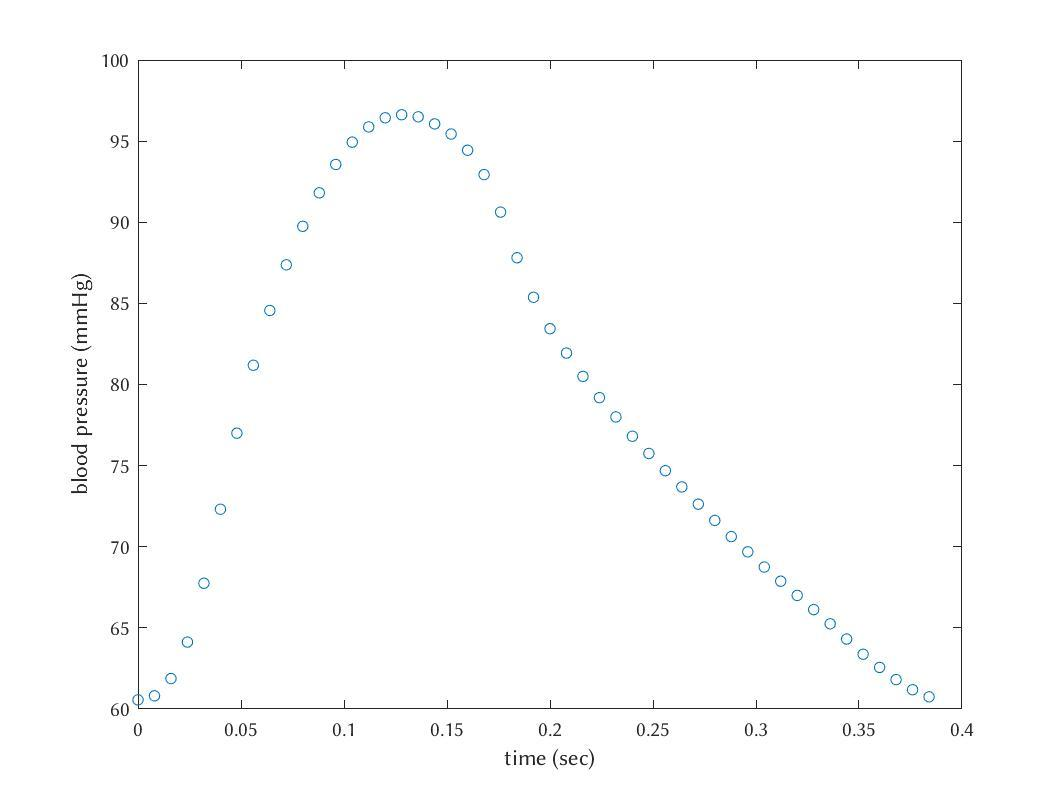

Denote the data points by $(t_i, y_i)$ for $i = 1, \ldots, m$. The data can be fit using a low-degree polynomial of the form


$$f(t) = c_1 + c_2 t + \cdots + c_n t^{n-1}, \quad n < m.$$


In the most general terms, the fitting function takes the form


$$f(t) = c_1 f_1(t) + \cdots + c_n f_n(t),$$


where $f_1, \ldots, f_n$ are known functions while $c_1, \ldots, c_n$ are to be determined to optimize the fit to the data. This optimization can be formulated as an $m \times n$ LLS problem of minimizing the 2-norm of the residual $\Vert \mathbf{y} - A \mathbf{c} \Vert_2$, where $A_{i,j} = f_j(t_i)$.

### (a)

Download the data file [**pressuredata.mat**](https://tek288a1.github.io/sp21m3607/exam/pressuredata.mat) and load it into MATLAB using `load pressuredata`. (Make sure the data file is in the same directory/folder as this mlx file.) This creates two vectors `t` and `y` containing time and blood pressure data, respectively. Use them to regenerate the plot above.

load pressuredata
% Make a labeled plot.



### (b)

Fit the data to a straight line, $f(t) = c_1 + c_2 t$. Solve for the coefficients using backslash. Superimpose the graph of the fitting line on your graph from the previous step, and compute the 2-norm of the residual $\Vert \mathbf{y} - A \mathbf{c} \Vert_2$, where $A_{i,j} = t_i^{j-1}$ is a *Vandermonde*-type matrix.

% Set up matrix A and solve for c using backslash


% Compute the residual norm.


% Plot



### (c)

Repeat part (b) for a quadratic and a cubic polynomial. The residual norm will get smaller in each case, but there is still a room for improvement.

### (d) 

Exploiting the fact that the data come from a periodic phenomenon (heart beats), adapt this general form to a periodic fitting function

$f(t) = c_1 + c_2 \cos \frac{2\pi t}{T} + c_3 \sin \frac{2\pi t}{T}  + c_4 \cos \frac{4\pi t}{T} + c_5 \sin \frac{4\pi t}{T}$, where $T = t_m - t_1$ (period).

As in the previous parts, solve for the coefficients using backslash, superimpose the graph of $f(t)$ to the plot of data points, and compute the residual norm. Comment on your observation.

## Problem 2 (Visualizng Matrix Norms: 3-D)

Recall that


$$\Vert A\Vert_p = \max_{\Vert \mathbf{x} \Vert_p = 1} \Vert A\mathbf{x} \Vert_p, \quad p \in [1, \infty].$$


In this problem, we generate three-dimensional visualization of this definition.

### (a)

Complete the program at the end of the live script which, given $p \in [1, \infty]$ and $A \in \mathbb{R}^{3 \times 3}$, approximates $\Vert A \Vert_p$ and plots the unit sphere in the $p$-norm and its image under $A$.

### (b)

Run the following code block:

A = [2 0 0;
     0 cos(pi/12) -sin(pi/12);
     0 sin(pi/12)  cos(pi/12)];
visMatrixNorms3D(A, 1);
visMatrixNorms3D(A, 3/2);
visMatrixNorms3D(A, 2);
visMatrixNorms3D(A, 4);

Depending on how you write the code, you may need to use `clf` or `hold off `in between function calls.

## Extra Credit (Koch Snowflakes)

Do **LM** 7.2--13. (This was an optional problem assigned for Homework 5.)

## Functions Used

### Visualization of Matrix Norms (Problem 2)

function norm_A = visMatrixNorms3D(A, p)
%% Basic checks
if size(A,1)~=3 || size(A,2)~=3
    error('A must be a 3-by-3 matrix.')
elseif p < 1
    error('p must be >= 1.')
end

%% Step 1: Initialization
nr_th = 41; nr_ph = 31;
th = linspace(0, 2*pi, nr_th);
ph = linspace(0, pi, nr_ph);
[T, P] = meshgrid(th, ph);
x1 = cos(T).*sin(P);
x2 = sin(T).*sin(P);
x3 = cos(P);
X = [x1(:), x2(:), x3(:)]';

%% Step 2: [FILL IN] Normalize columns of X into unit vectors





%% Step 3: [FILL IN] Form Y = A*X and then calculate norms of columns of Y





%% Step 4: [FILL IN] Calculate p-norm of A (approximate)





%% Step 5: [FILL IN] Generate surface plots





end